`In the name of God`

# Blind Source Separation

## HW #5

**Maryam Riazi**

**810197518**

### Introduction

TrainData_class1 = zeromean(TrainData_class1);
TrainData_class2 = zeromean(TrainData_class2);
TestData = zeromean(TestData);

### Q1)

trainC1_size = size(TrainData_class1);
trainC2_size = size(TrainData_class2);
Rx1 = zeros(trainC1_size(1),trainC1_size(1));
Rx2 = zeros(trainC2_size(1),trainC2_size(1));


%For loop over over each Subject %Class1
for k = 1:trainC1_size(3)
    X = TrainData_class1(:,:,k);
    Rx1 = Rx1+X*X.';
end

%For loop over over each Subject %Class2
for k = 1:trainC2_size(3)
    X = TrainData_class2(:,:,k);
    Rx2 = Rx2+X*X.';
end

Rx1 = (1/trainC1_size(3))*Rx1;
Rx2 = (1/trainC2_size(3))*Rx2;

[W,lambda] = eig(Rx1,Rx2);
[~,series] = sort(diag(lambda),'descend');

%Sorting from the highest eigenvalue to the lowest
W = W(:,series);


Normalize Column wise:

Here I am not sure about the function because without normalizing the variances are more different. However as it is mentioned in the Question, I normalized W column wise...

Here if the Questions order was normalizing we should use the normalize function but I am not sure about that and I think It means only rescaling!


% W = normalize(W,2);

W1 = W(:,1);
W30 = W(:,30);

% Normalizing if it means scaling
W1 = W1/max(W1);
W30 = W30/max(W30);

filtered1 = [W1.';W30.']*TrainData_class1(:,:,49);
fprintf('var{wT1.X1(49)} = %f',var(filtered1(1,:)));

var{wT1.X1(49)} = 10.601210

fprintf('var{wT30.X1(49)} = %f',var(filtered1(2,:)));

var{wT30.X1(49)} = 1.922711

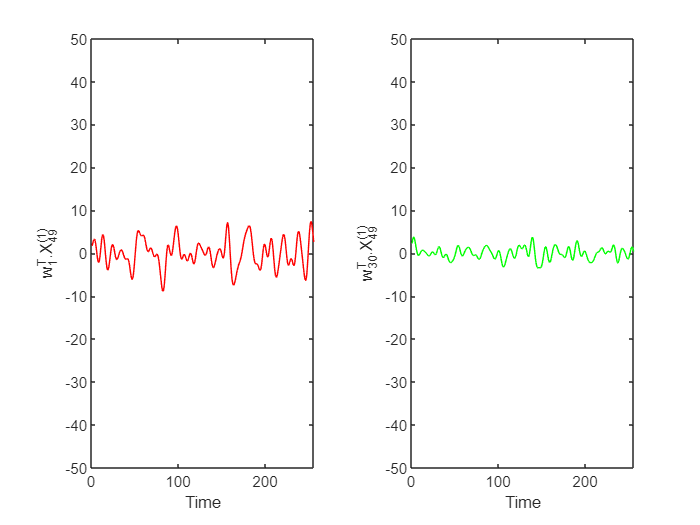

figure
tiledlayout(1,2)
nexttile
plot(filtered1(1,:),'color','red')
xlim([0,256])
ylim([-50,50])
xlabel('Time')
ylabel('w_{1}^T.X_{49}^{(1)}')

nexttile
plot(filtered1(2,:),'green')
xlim([0,256])
ylim([-50,50])
xlabel('Time')
ylabel('w_{30}^T.X_{49}^{(1)}')

filtered2 = [W1.';W30.']*TrainData_class2(:,:,49);
fprintf('var(wT1.X2(49)) = %f',var(filtered2(1,:)));

var(wT1.X2(49)) = 6.550035

fprintf('var(wT30.X2(49)) = %f',var(filtered2(2,:)));

var(wT30.X2(49)) = 14.569599

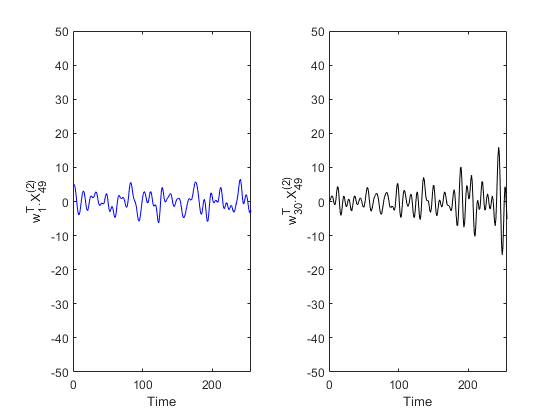

figure
tiledlayout(1,2)
nexttile
plot(filtered2(1,:),'color','blue')
xlim([0,256])
ylim([-50,50])
xlabel('Time')
ylabel('w_{1}^T.X_{49}^{(2)}')

nexttile
plot(filtered2(2,:),'color','black')
xlim([0,256])
ylim([-50,50])
xlabel('Time')
ylabel('w_{30}^T.X_{49}^{(2)}')

### Q2)

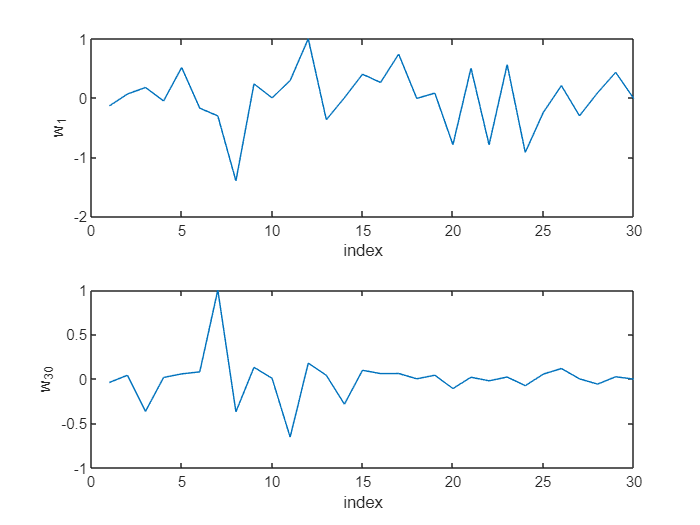

figure
tiledlayout(2,1)
nexttile
plot(W1)
xlabel('index')
ylabel('w_1')
nexttile
plot(W30)
xlabel('index')
ylabel('w_{30}')

As it is shown above, During task1 the part of the brain to which sensor 8 is connected, is the most active. 

Similarly the most active part of the brain when doing task 2 is the one connected to sensor 7.

### Q3)

W_14channels = [W(:,1:7) W(:,24:30)].';

train_set1 = cspfilter(W_14channels,TrainData_class1);
train_set2 = cspfilter(W_14channels,TrainData_class2);

mean1 = mean(train_set1).';
mean2 = mean(train_set2).';

cov1 = cov(train_set1);
cov2 = cov(train_set2);

[WLDA,landa] = eig((mean1-mean2)*(mean1-mean2).',cov1+cov2);
%Sorting from the highest eigenvalue to the lowest
[~,seriesLDA] = sort(diag(landa),'descend');
WLDA = WLDA(:,seriesLDA(1))

WLDA =     1.9530
  312.7866
   -1.3676
  157.5076
   -4.4032
  158.3735
  199.7564
   47.2718
  -53.6375
 -342.8187


% WLDA = normalize(WLDA)
WLDA=WLDA/max(WLDA);

c = (WLDA.'*mean1 + WLDA.'*mean2)/2

c = 0.0074

### Q4)

test_set = cspfilter(W_14channels,TestData);
prediction = predict(test_set,WLDA,c)

prediction =      1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     2     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     2     1     2     1     1


### Q5)

[Accuracy, Sum_of_correct_predictions] = acc(prediction,TestLabel)

Accuracy = 85

Sum_of_correct_predictions = 34

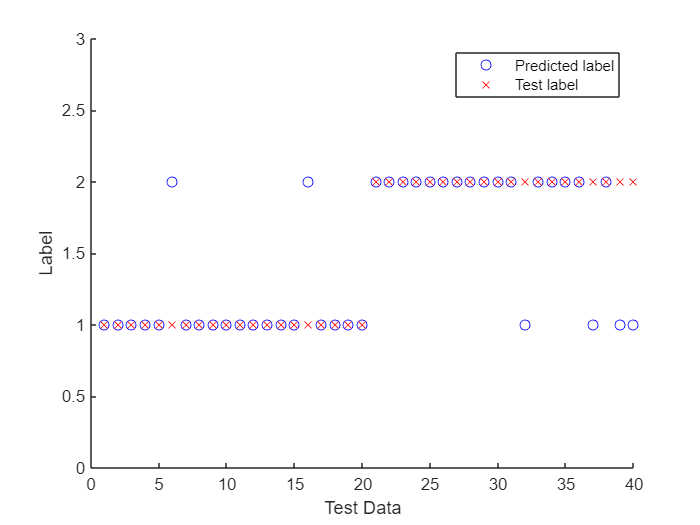

figure
hold on
scatter(1:length(prediction),prediction,'Blue')
scatter(1:length(TestLabel),TestLabel,'red','x')
ylim([0,3])
ylabel('Label')
xlabel('Test Data')
legend('Predicted label','Test label','Location','northeast')
hold off

Functions.

function zm_data = zeromean(data)
data_size = size(data);
zm_data = zeros(data_size);
for k = 1:data_size(3)
    avg = mean(data(:,:,k),2);
    zm_data(:,:,k) = data(:,:,k)-avg;
end
end

function filtered_set = cspfilter(W,Data)
data_size = size(Data);
filtered_set = zeros(data_size(3),size(W,1));
for k = 1:data_size(3)
    filtered = W*Data(:,:,k);
    avg = mean(filtered,2);
    variance = sum((filtered-avg).^2,2)/data_size(2);
    filtered_set(k,:) = variance.';
end
end

function label = predict(test,WLDA,c)
test_size = size(test);
label = zeros(1,test_size(1));
for i = 1:test_size(1)
    X = test(i,:).';
    if  WLDA.'*X > c
        label(i) = 1;
    else
        label(i) = 2;
    end    
end
end

function [accuracy, sumofcorrect] = acc(prediction,TestLabel)
sumofcorrect = 0;
for i = 1:length(TestLabel)
if TestLabel(i) == prediction(i)
    sumofcorrect = sumofcorrect+1;
end
accuracy = sumofcorrect/length(TestLabel)*100;
end
end
